s = tf('s');
G = (s+1)/(s^2 + 10*s + 1000);
Wu = 10^-6;
Gd = (s+10000)/(10*s+1000)

Gd =
 
   s + 10000
  -----------
  10 s + 1000
 
Continuous-time transfer function.



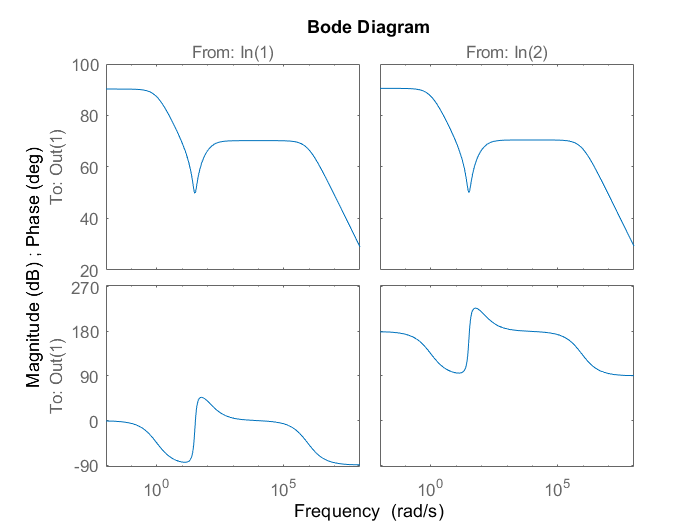


% Generalized plant
P = [Gd -1 0 G;0 0 0 Wu;0 1 0 0;Gd 0 1 G];

% H-inf Controller synthesis

% nmeans = no. of signals in v, and ncont is number signals in u
Kc = hinfsyn(P,2,1);

% Bode plot of controller
bode(Kc)